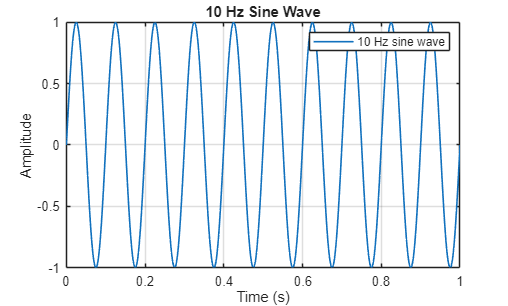

fs = 1000;
t = 0:1/fs:1;
x = sin(2*pi*10*t);

figure;
plot(t, x, 'LineWidth', 1.2);
title('10 Hz Sine Wave');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
legend('10 Hz sine wave');

%%saveas(gcf, 'original_signal.png');
%%clear

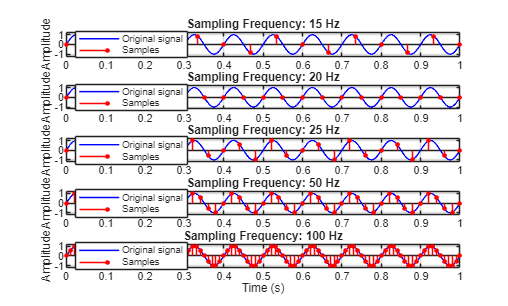

fs = 1000;
t = 0:1/fs:1;
x = sin(2*pi*10*t);
samplingFrequencies = [15 20 25 50 100];

figure;
for k = 1:numel(samplingFrequencies)
    fsSample = samplingFrequencies(k);
    ts = 0:1/fsSample:1;
    xs = sin(2*pi*10*ts);

    subplot(5, 1, k);
    plot(t, x, 'b', 'LineWidth', 1.1);
    hold on;
    stem(ts, xs, 'r', 'filled', 'MarkerSize', 3);
    hold off;
    grid on;
    xlim([0 1]);
    ylim([-1.2 1.2]);
    title(sprintf('Sampling Frequency: %d Hz', fsSample));
    ylabel('Amplitude');
    if k == 5
        xlabel('Time (s)');
    end
    legend('Original signal', 'Samples', 'Location', 'best');
end

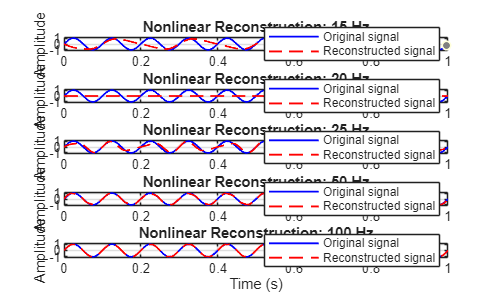

figure;
for k = 1:numel(samplingFrequencies)
    fsSample = samplingFrequencies(k);
    ts = 0:1/fsSample:1;
    xs = sin(2*pi*10*ts);

    xReconstructed = interp1(ts, xs, t, 'pchip');

    subplot(5, 1, k);
    plot(t, x, 'b', 'LineWidth', 1.1);
    hold on;
    plot(t, xReconstructed, 'r--', 'LineWidth', 1.1);
    hold off;
    grid on;
    xlim([0 1]);
    ylim([-1.2 1.2]);
    title(sprintf('Nonlinear Reconstruction: %d Hz', fsSample));
    ylabel('Amplitude');
    if k == numel(samplingFrequencies)
        xlabel('Time (s)');
    end
    legend('Original signal', 'Reconstructed signal', 'Location', 'best');
end